# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 22-May-2022 02:57:03

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = imageInputLayer([512 512 1],"Name","imageinput_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = imageInputLayer([512 512 1],"Name","imageinput_2");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = convolution2dLayer([5 5],32,"Name","conv_6","Padding","same");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = convolution2dLayer([3 3],32,"Name","conv_1","Padding","same");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = convolution2dLayer([7 7],32,"Name","conv_7","Padding","same");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = convolution2dLayer([5 5],32,"Name","conv_4","Padding","same");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = convolution2dLayer([7 7],32,"Name","conv_5","Padding","same");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(3,"Name","depthcat_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([5 5],"Name","maxpool_2","Padding","same")
    transposedConv2dLayer([3 3],32,"Name","transposed-conv_1","Cropping","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],32,"Name","conv_10","Padding","same")
    batchNormalizationLayer("Name","batchnorm_4")
    reluLayer("Name","relu_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([5 5],32,"Name","conv_11","Padding","same")
    batchNormalizationLayer("Name","batchnorm_5")
    reluLayer("Name","relu_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([7 7],32,"Name","conv_12","Padding","same")
    batchNormalizationLayer("Name","batchnorm_6")
    reluLayer("Name","relu_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(3,"Name","depthcat_4");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = imageInputLayer([512 512 1],"Name","imageinput_3");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = convolution2dLayer([5 5],32,"Name","conv_9","Padding","same");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = convolution2dLayer([7 7],32,"Name","conv_3","Padding","same");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = convolution2dLayer([3 3],32,"Name","conv_8","Padding","same");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(3,"Name","depthcat_3");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    batchNormalizationLayer("Name","batchnorm_3")
    reluLayer("Name","relu_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    averagePooling2dLayer([5 5],"Name","avgpool2d","Padding","same")
    transposedConv2dLayer([3 3],32,"Name","transposed-conv_3","Cropping","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([7 7],32,"Name","conv_19","Padding","same")
    batchNormalizationLayer("Name","batchnorm_12")
    reluLayer("Name","relu_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],32,"Name","conv_17","Padding","same")
    batchNormalizationLayer("Name","batchnorm_10")
    reluLayer("Name","relu_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([5 5],32,"Name","conv_18","Padding","same")
    batchNormalizationLayer("Name","batchnorm_11")
    reluLayer("Name","relu_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(3,"Name","depthcat_6");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = convolution2dLayer([3 3],32,"Name","conv_2","Padding","same");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(3,"Name","depthcat_2");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([5 5],"Name","maxpool_1","Padding","same")
    transposedConv2dLayer([3 3],32,"Name","transposed-conv_2","Cropping","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([5 5],32,"Name","conv_15","Padding","same")
    batchNormalizationLayer("Name","batchnorm_8")
    reluLayer("Name","relu_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([7 7],32,"Name","conv_16","Padding","same")
    batchNormalizationLayer("Name","batchnorm_9")
    reluLayer("Name","relu_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    batchNormalizationLayer("Name","batchnorm_2")
    reluLayer("Name","relu_2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],32,"Name","conv_14","Padding","same")
    batchNormalizationLayer("Name","batchnorm_7")
    reluLayer("Name","relu_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = depthConcatenationLayer(3,"Name","depthcat_5");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(6,"Name","addition")
    convolution2dLayer([3 3],2,"Name","conv_13","Padding","same")
    softmaxLayer("Name","softmax")
    pixelClassificationLayer("Name","pixel-class")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"imageinput_1","conv_1");
lgraph = connectLayers(lgraph,"imageinput_1","conv_4");
lgraph = connectLayers(lgraph,"imageinput_1","conv_5");
lgraph = connectLayers(lgraph,"imageinput_2","conv_6");
lgraph = connectLayers(lgraph,"imageinput_2","conv_7");
lgraph = connectLayers(lgraph,"imageinput_2","conv_2");
lgraph = connectLayers(lgraph,"conv_6","depthcat_2/in1");
lgraph = connectLayers(lgraph,"conv_1","depthcat_1/in1");
lgraph = connectLayers(lgraph,"conv_7","depthcat_2/in3");
lgraph = connectLayers(lgraph,"conv_4","depthcat_1/in2");
lgraph = connectLayers(lgraph,"conv_5","depthcat_1/in3");
lgraph = connectLayers(lgraph,"depthcat_1","maxpool_2");
lgraph = connectLayers(lgraph,"depthcat_1","batchnorm_1");
lgraph = connectLayers(lgraph,"transposed-conv_1","conv_10");
lgraph = connectLayers(lgraph,"transposed-conv_1","conv_11");
lgraph = connectLayers(lgraph,"transposed-conv_1","conv_12");
lgraph = connectLayers(lgraph,"relu_5","depthcat_4/in2");
lgraph = connectLayers(lgraph,"relu_4","depthcat_4/in1");
lgraph = connectLayers(lgraph,"relu_1","addition/in1");
lgraph = connectLayers(lgraph,"relu_6","depthcat_4/in3");
lgraph = connectLayers(lgraph,"depthcat_4","addition/in4");
lgraph = connectLayers(lgraph,"imageinput_3","conv_9");
lgraph = connectLayers(lgraph,"imageinput_3","conv_3");
lgraph = connectLayers(lgraph,"imageinput_3","conv_8");
lgraph = connectLayers(lgraph,"conv_9","depthcat_3/in2");
lgraph = connectLayers(lgraph,"conv_3","depthcat_3/in3");
lgraph = connectLayers(lgraph,"conv_8","depthcat_3/in1");
lgraph = connectLayers(lgraph,"depthcat_3","batchnorm_3");
lgraph = connectLayers(lgraph,"depthcat_3","avgpool2d");
lgraph = connectLayers(lgraph,"transposed-conv_3","conv_19");
lgraph = connectLayers(lgraph,"transposed-conv_3","conv_17");
lgraph = connectLayers(lgraph,"transposed-conv_3","conv_18");
lgraph = connectLayers(lgraph,"relu_10","depthcat_6/in1");
lgraph = connectLayers(lgraph,"relu_12","depthcat_6/in3");
lgraph = connectLayers(lgraph,"relu_11","depthcat_6/in2");
lgraph = connectLayers(lgraph,"depthcat_6","addition/in6");
lgraph = connectLayers(lgraph,"relu_3","addition/in3");
lgraph = connectLayers(lgraph,"conv_2","depthcat_2/in2");
lgraph = connectLayers(lgraph,"depthcat_2","maxpool_1");
lgraph = connectLayers(lgraph,"depthcat_2","batchnorm_2");
lgraph = connectLayers(lgraph,"transposed-conv_2","conv_15");
lgraph = connectLayers(lgraph,"transposed-conv_2","conv_16");
lgraph = connectLayers(lgraph,"transposed-conv_2","conv_14");
lgraph = connectLayers(lgraph,"relu_7","depthcat_5/in1");
lgraph = connectLayers(lgraph,"relu_2","addition/in2");
lgraph = connectLayers(lgraph,"relu_9","depthcat_5/in3");
lgraph = connectLayers(lgraph,"relu_8","depthcat_5/in2");
lgraph = connectLayers(lgraph,"depthcat_5","addition/in5");

## Plot Layers

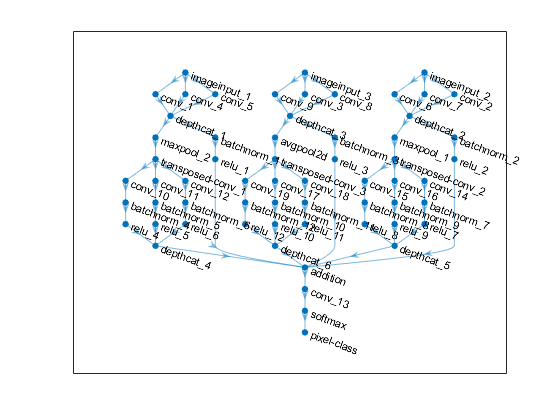

plot(lgraph);